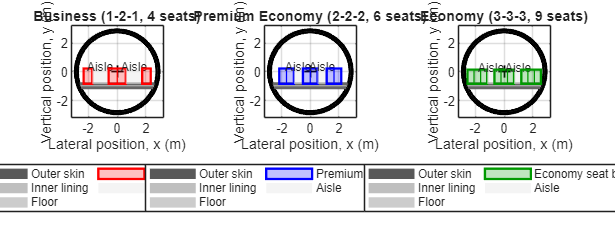

%% Fuselage Cross-Section with Cabin Arrangements (2-layer shell)
clear; clc; close all;

IN = 0.0254;                            % inch to metre

%% Geometry
P.D_inner = 5.478;                      % Inner diameter [m]
P.D_outer = 5.8336;                     % Outer diameter [m]
P.R_inner = P.D_inner / 2;
P.R_outer = P.D_outer / 2;

P.t_inner_layer = 0.04;                 % Inner lining layer thickness [m]
P.R_mid = P.R_inner + P.t_inner_layer;  % Boundary between the two wall layers

P.t_floor = 0.05 * P.D_inner;           % Floor thickness [m]
P.yU = -0.8395;                         % Floor upper surface [m]
P.yL = P.yU - P.t_floor;                % Floor lower surface [m]

%% Cabin arrangement parameters (inches -> metres)
P.clear_w = 2  * IN;                    % Side clearance to inner wall [m]

% Aisle widths per class [m]
aisle_bus = 45 * IN;
aisle_pre = 25 * IN;
aisle_eco = 20 * IN;

% Seat block heights (above floor)
h_bus = 42 * IN;
h_pre = 42 * IN;
h_eco = 39 * IN;

% Seat widths
w_bus = 23.5 * IN;
w_pre = 20   * IN;
w_eco = 19   * IN;

cls(1).name = 'Business';        cls(1).pattern = [1 2 1]; cls(1).seatW = w_bus; cls(1).height = h_bus; cls(1).aisle_w = aisle_bus; cls(1).color = [1 0 0];
cls(2).name = 'Premium Economy'; cls(2).pattern = [2 2 2]; cls(2).seatW = w_pre; cls(2).height = h_pre; cls(2).aisle_w = aisle_pre; cls(2).color = [0 0 1];
cls(3).name = 'Economy';         cls(3).pattern = [3 3 3]; cls(3).seatW = w_eco; cls(3).height = h_eco; cls(3).aisle_w = aisle_eco; cls(3).color = [0 0.6 0];

%% Plot: one panel per cabin class
figure('Color', 'w', 'Position', [100 100 1500 560]);
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

for k = 1:numel(cls)
    ax = nexttile;
    hold(ax, 'on'); axis(ax, 'equal'); box(ax, 'on'); grid(ax, 'on');

    drawFuselageBase(ax, P);
    drawCabinClass(ax, P, cls(k));

    xlabel(ax, 'Lateral position, x (m)');
    ylabel(ax, 'Vertical position, y (m)');
    patternStr = strjoin(arrayfun(@num2str, cls(k).pattern, 'UniformOutput', false), '-');
    title(ax, sprintf('%s (%s, %d seats)', cls(k).name, patternStr, sum(cls(k).pattern)));

    xlim(ax, [-3.2 3.2]);
    ylim(ax, [-3.2 3.2]);
    legend(ax, 'Location', 'southoutside', 'NumColumns', 2);
    hold(ax, 'off');
end


%% ========================= Local functions =========================

function drawFuselageBase(ax, P)
    th = linspace(0, 2*pi, 500);
    xo = P.R_outer * cos(th); yo = P.R_outer * sin(th);
    xm = P.R_mid   * cos(th); ym = P.R_mid   * sin(th);
    xi = P.R_inner * cos(th); yi = P.R_inner * sin(th);

    % Layer 1: outer skin (R_mid to R_outer)
    patch(ax, [xo fliplr(xm)], [yo fliplr(ym)], [0.35 0.35 0.35], ...
        'EdgeColor', 'none', 'DisplayName', 'Outer skin');

    % Layer 2: inner lining (R_inner to R_mid)
    patch(ax, [xm fliplr(xi)], [ym fliplr(yi)], [0.75 0.75 0.75], ...
        'EdgeColor', 'none', 'DisplayName', 'Inner lining');

    % Boundaries
    plot(ax, xo, yo, 'k-', 'LineWidth', 2,   'HandleVisibility', 'off');
    plot(ax, xi, yi, 'k-', 'LineWidth', 1.5, 'HandleVisibility', 'off');
    plot(ax, xm, ym, 'k:', 'LineWidth', 0.8, 'HandleVisibility', 'off');

    % Cabin floor (clipped to inner wall)
    xU = sqrt(P.R_inner^2 - P.yU^2);
    xL = sqrt(P.R_inner^2 - P.yL^2);
    patch(ax, [-xU xU xL -xL], [P.yU P.yU P.yL P.yL], [0.8 0.8 0.8], ...
        'EdgeColor', 'none', 'DisplayName', 'Floor');
    plot(ax, [-xU xU], [P.yU P.yU], '-', 'Color', [0.4 0.4 0.4], 'LineWidth', 2, 'HandleVisibility', 'off');
    plot(ax, [-xL xL], [P.yL P.yL], '-', 'Color', [0.4 0.4 0.4], 'LineWidth', 2, 'HandleVisibility', 'off');

    % Centre point
    plot(ax, 0, 0, 'k+', 'MarkerSize', 8, 'LineWidth', 1.2, 'HandleVisibility', 'off');
end

function drawCabinClass(ax, P, c)
    nSeats  = sum(c.pattern);
    nAisles = numel(c.pattern) - 1;
    aisle   = c.aisle_w;                % class-specific aisle width [m]

    % Shrink seat width if the layout does not fit at floor level
    wAvail = 2 * sqrt(P.R_inner^2 - P.yU^2) - 2 * P.clear_w;
    seatW  = min(c.seatW, (wAvail - nAisles * aisle) / nSeats);
    totalW = nSeats * seatW + nAisles * aisle;

    h  = c.height;                      % class-specific seat block height
    y0 = P.yU;
    x  = -totalW / 2;

    for b = 1:numel(c.pattern)
        bw = c.pattern(b) * seatW;
        hv = 'off';
        if b == 1, hv = 'on'; end

        % Seat block: transparent shade with coloured edge
        patch(ax, [x x+bw x+bw x], [y0 y0 y0+h y0+h], c.color, ...
            'FaceAlpha', 0.25, 'EdgeColor', c.color, 'LineWidth', 1.5, ...
            'DisplayName', sprintf('%s seat block', c.name), ...
            'HandleVisibility', hv);

        % Individual seat dividers
        for s = 1:c.pattern(b) - 1
            xd = x + s * seatW;
            plot(ax, [xd xd], [y0 y0+h], '-', 'Color', c.color, ...
                'LineWidth', 0.8, 'HandleVisibility', 'off');
        end
        x = x + bw;

        % Aisle after this block
        if b < numel(c.pattern)
            patch(ax, [x x+aisle x+aisle x], [y0 y0 y0+h y0+h], [0.93 0.93 0.93], ...
                'FaceAlpha', 0.6, 'EdgeColor', 'none', ...
                'DisplayName', 'Aisle', 'HandleVisibility', hv);
            text(ax, x + aisle/2, y0 + h + 0.12, 'Aisle', ...
                'HorizontalAlignment', 'center', 'FontSize', 8);
            x = x + aisle;
        end
    end
end